# Getting simulated data from an AR model

## Introduction

In this tutorial you will learn how to simulate time series from a univariate random process defined by an AR model. 

The dataset employed in this tutorial is '*database/case_03_AR*', which includes a restricted AR model employed in Section 3.1 of** [1]**. In this tutorial, a number of arbitraty $k$ realisations of the process is performed. As a result, $k$ time series of length $N$ are obtained and stored in a `data` object.

## Tutorial

First of all, add mVARbox to path, set the tutorial parameters.

setmVARboxPath

mVARbox path has been added to MATLAB path



clear
clc
close all


%%% Parameters

k = 5;     % number of realisations of the process
N = 100;   % data length

M = 30;    % maximum lag for the autocovariance functions to be estimated


%%% Plot parameters
font_size       = 16;
figure_position = [0 0 1000 400];
CC              = colororder;
color_realisations  = 0.5*[1 1 1];
color_true          = CC(1,:);
color_ensemble      = CC(3,:);

Load the dataset. It consists of a restricted AR model. Check the fields required by function `get_data_AR`. For details related to the fields of these objects, see functions `initialise_`AR.

load case_03_AR AR

fprintf('j_vector is [%d, %d, %d] \n', AR.restricted_parameters.j_vector)

j_vector is [1, 2, 5] 


fprintf('a_vector is [%.1f, %.1f, %.1f] \n', AR.restricted_parameters.a_vector)

a_vector is [1.2, -0.5, 0.1] 


fprintf('b is %.1f \n',AR.restricted_parameters.b)

b is 0.5 


Initialise a `data` object with the fields required by function `get_data_AR`.

data = initialise_data('N',N,'k',k);

Obtain the realisations.

data = get_data_AR(AR, data);

Plot the time series

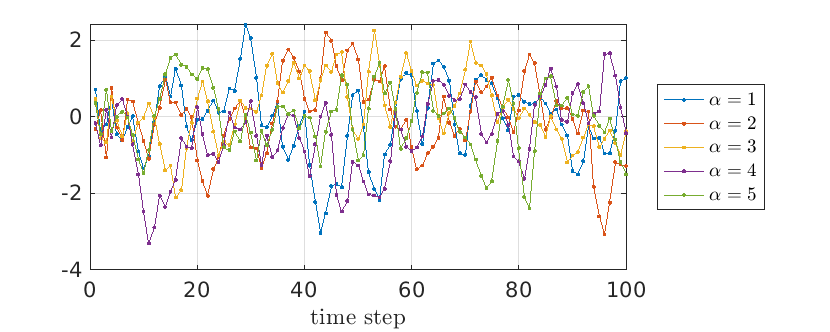

figure

y = data.y_values;
plot(y,'.-')

grid on
xlabel('time step','Interpreter','latex')
legend(strcat('$\alpha= ',strcat(num2str((1:k)'),'$')),...
       'Interpreter','latex','Location','eastoutside')

set(gca,'fontsize',font_size)

set(gcf,'Position',figure_position)

You can add a $\Delta t$ to field `delta_x` in data object using function `fun_append_data`. By doing so, field `data.x_values` is automatically filled (this operation is handled by `fun_check_data`, called at the end of function `fun_append_data`).

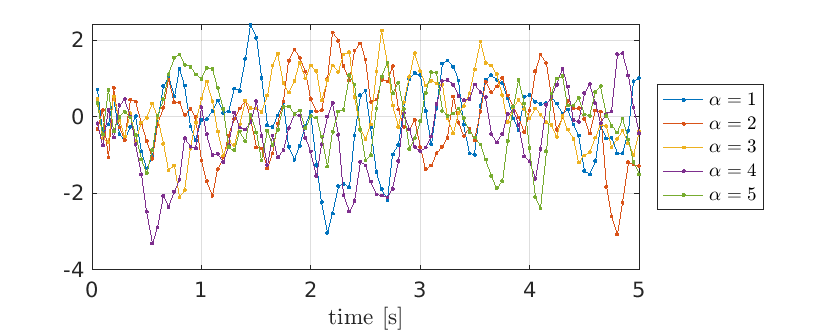

delta_t = 0.05;

data = fun_append_data(data,'delta_x',delta_t);

figure

x = data.x_values;
y = data.y_values;
plot(x,y,'.-')

grid on
xlabel('time [s]','Interpreter','latex')
legend(strcat('$\alpha= ',strcat(num2str((1:k)'),'$')),...
       'Interpreter','latex','Location','eastoutside')

set(gca,'fontsize',font_size)

set(gcf,'Position',figure_position)

In order to check that the generated time series reproduce the statistical features of the AR model, the true autocovariance function of the AR model and the estimated autocovariance functions from the data are to be compared. For more details on these operations, check tutorials *getting_gamma_from_AR* and *getting_gamma_from_data*.

Get the true autocovariance function of the AR model, $\gamma^{AR}[m]$.

gamma_fun0 = initialise_gamma('M', M);
gamma_fun_AR = get_gamma_AR (AR, gamma_fun0);

Get the sample autocovariance function of the realisations, $\hat\gamma^{\alpha}[m]$, $\alpha = 1,...,k$.

gamma_fun0 = initialise_gamma('method', 'biased_matlab', 'M', M);

gamma_fun_data_cell = cell(k,1);

for ii=1:k
    k_index = ii;
    gamma_fun_data = get_gamma_data(data, gamma_fun0, k_index);
    gamma_fun_data_cell{ii} = gamma_fun_data;
end


Compute the ensemble autocovariance function (the average of the samples), $\hat\gamma^{\bar{\alpha}}[m]$

y_ensemble = zeros(2*M+1,1);
for ii=1:k
    gamma_fun_data = gamma_fun_data_cell{ii};
    y = gamma_fun_data.y_values;
    y_ensemble = y_ensemble+(1/k)*y;
end

Plot the true, the sample and the ensemble autocovariance functions.

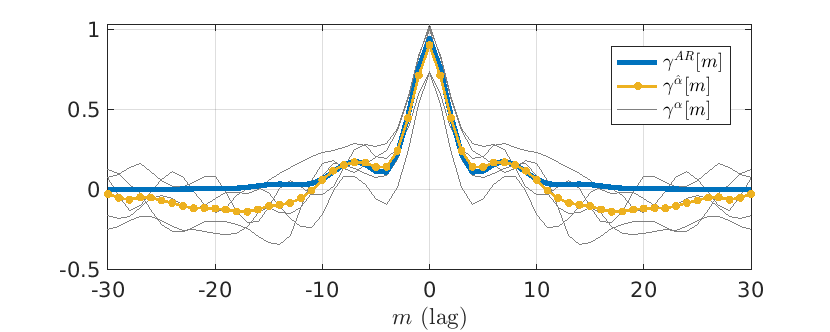

figure

% sample autocovariance functions
for ii=1:k
    gamma_fun_data = gamma_fun_data_cell{ii};
    x = gamma_fun_data.xlag_values;
    y = gamma_fun_data.y_values;
    h_sample = plot(x,y,'-','color',color_realisations);
    hold on
end


% true autocovariance function of the AR model
x = gamma_fun_AR.xlag_values;
y = gamma_fun_AR.y_values;
h_true = plot(x,y,'-','LineWidth',4,'color',color_true);

% ensemble autocovariance function
h_ensemble = plot(x,y_ensemble,'.-','color',color_ensemble,...
                  'LineWidth',2,'markersize',15);

grid on
legend([h_true, h_ensemble, h_sample],...
       {'$\gamma^{AR}[m]$',...
        '$\gamma^{\hat{\alpha}}[m]$',...
        '$\gamma^{\alpha}[m]$'},...
        'Interpreter','latex',...
        'Location','best')
xlabel('$m$ (lag)','Interpreter','latex')

set(gca,'fontsize',font_size)

set(gcf,'position',figure_position)

## Remarks

- The ensemble autocovariance function tends to the true autocovariance function for increasing number of realisations and longer realisations. You can check this by increasing the value of parameters `k` and `N`.